# 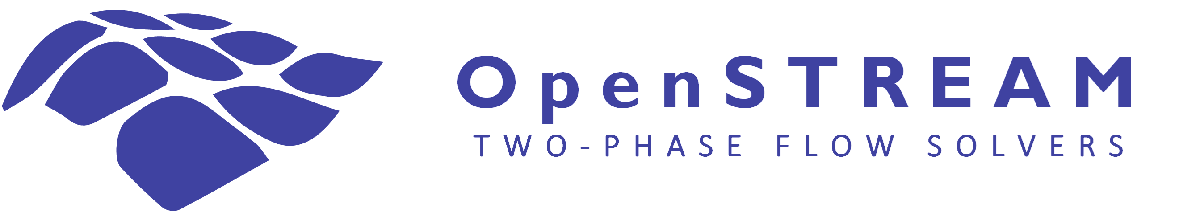

# Tutorial #5: Four-field solver capabilities

In this tutorial, you will explore capabilities specific to the OpenSTREAM four-field solver. The four-field formulation extends the three-field approach by separating the liquid film into a continuous base-film field and a disturbance-wave field, while retaining the droplet field and the mixture-model vapor solution.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter. The case is used to examine film decomposition, wave development, base-film depletion, and field momentum and mass exchanges.

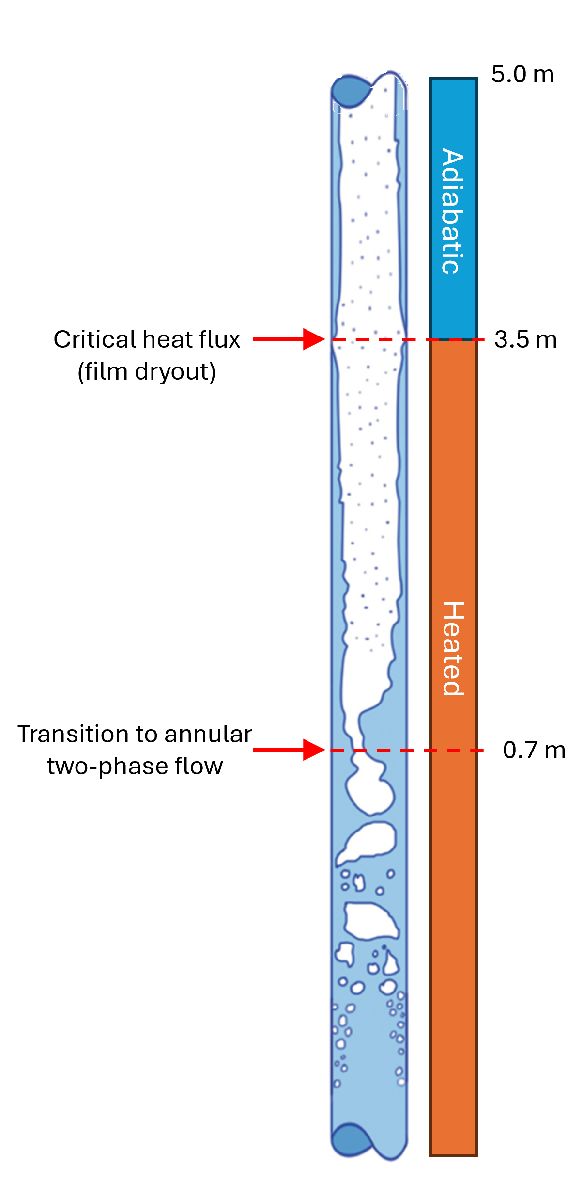

Learning objectives:

- Input files and four-field model sets

- Default four-field calculation

- Base-film, wave, droplet, and vapor transport

- Film thicknesses and wave geometry

- Base-film and wave fractions

- Film splitting at the onset of annular flow

- Equilibrium base-film thickness models

- Equilibrium and relaxation wave-frequency models

- Full momentum formulations

- Base-film, wave, and droplet exchange terms

- Pseudo-time convergence history

- Physical transient calculation

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up the MATLAB path

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

## Input files

Import the required packages.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*
import Solvers.FourField.*

Display the model file and locate the TUTORIAL5 entries.

type('../inputs/models.inp')

The tutorial uses the following model sets:

- TUTORIAL5A uses the documented four-field defaults.

- TUTORIAL5B prescribes a base-film fraction of 0.30 at the onset of annular flow.

- TUTORIAL5C selects the YPLUS equilibrium base-film-thickness model.

- TUTORIAL5D imposes the local equilibrium wave frequency.

- TUTORIAL5E uses full base-film, wave, and droplet momentum transport, relaxation of wave frequency, and the vapor-shear-plus-droplet-mass wave/base interaction model.

 Display the options, geometry, and steady-state boundary conditions.

type('../inputs/options.inp')
type('../inputs/geom.inp')
type('../inputs/tutorial1.inp')

## Default four-field calculation

Construct TUTORIAL5A. Warnings are temporarily suppressed to keep the tutorial concise. During development, leaving warnings enabled is recommended.

% Construct the inputSet.
warning off
inputSetA = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5A', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

The solver requires a solved mixture solution. If one is not supplied, the constructor creates and solves one automatically.

% Create the four-field solver.
ffSolverA = FourFieldSolver(inputSetA);

Inspect the initialized solver. The liquid-film and droplet fields are stored in separate objects, while the solved mixture solver is retained by the four-field solver. Within the film object, the base-film and disturbance-wave fields are represented by separate objects. The four-field solver calculates the base-film, disturbance-wave, and droplet fields separately while reusing the vapor-field solution from the mixture solver. The film object also provides aggregate liquid-film properties, such as total film mass flow rate and representative film velocity, derived from the solved base-film and disturbance-wave fields.

disp(ffSolverA)
display(ffSolverA.film(1))
% Solve the four-field solver.
ffSolverA.solve();

Plot the mass flow rates for the total liquid, droplets, total film, disturbance waves, base film, minimum base film, and vapor.

ffSolverA.plotz('display','W','resize',1);

With the default models, the calculated base-film and disturbance-wave mass flow rates are similar. This distribution is likely not physically realistic, because disturbance waves are generally expected to carry most of the total liquid-film mass under the modeled annular-flow conditions. For this case, other closure models or further development and validation of closure models are therefore required.

The total liquid-film mass flow rate, obtained as the sum of the base-film and disturbance-wave mass flow rates, remains consistent with the film mass flow rate calculated directly by the three-field solver in Tutorial 4. This agreement is expected because mass transfer between the base-film and disturbance-wave fields is internal to the total film and cancels when their mass conservation equations are summed. The resulting total-film source terms for entrainment, deposition, and evaporation are therefore the same as those used by the corresponding three-field model.

Complete liquid-film dryout occurs at the end of the heated section, at an elevation of 3.5 m. In this simulation, the disturbance-wave field is depleted before the base-film field. In the downstream adiabatic section, droplet deposition regenerates the liquid film, primarily by replenishing the disturbance-wave field. Consequently, the wave mass flow rate progressively recovers, while the base-film mass flow rate increases to a lesser extent.

Plot field velocities.

ffSolverA.plotz('display','U','resize',1);

The base film, disturbance waves, entrained droplets, and vapor can generally travel at different velocities. In the default configuration, however, the droplet momentum model prescribes a droplet-to-vapor velocity ratio of one. The droplet momentum conservation equation is therefore not solved, and the droplet velocity is set equal to the vapor velocity.

The base-film and disturbance-wave velocities increase along the channel as the vapor velocity and the corresponding interfacial shear increase. The disturbance waves travel faster than the base film, as expected from their stronger interaction with the vapor flow.

Plot mass flow rates per unit perimeter and film thickness measures.

ffSolverA.plotz( ...
    'display', {'WL','THICK'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The thickness plot displays the total film thickness together with the separate geometrical scales of the base-film and disturbance-wave fields. These include the wave-equivalent thickness, wave amplitude, calculated and equilibrium base-film thicknesses, and minimum base-film thickness. The disturbance-wave amplitude is the largest transverse length scale. The minimum base-film thickness represents the most depleted condition of the base film during the interval between successive waves, immediately before the next disturbance wave arrives and replenishes it. Its evolution reflects wall evaporation and droplet deposition during that interval.

Plot vapor, wave, and base-film Reynolds numbers.

ffSolverA.plotz('display','RE','resize',1);

The vapor, disturbance-wave, and base-film Reynolds numbers characterize the relative importance of inertial and viscous effects in the corresponding fields and may be used as inputs to closure models.

Save the baseline result if desired.

ffSolverA.save('name','ffSolverA','showpath',false);

### Wave frequency and axial scales

Plot the calculated disturbance-wave frequency and its equilibrium value.

ffSolverA.plotz('display','FREQUENCY','resize',1);

As expected, the calculated wave frequency initially lags behind its equilibrium value and progressively approaches it along the downstream adiabatic section. This behavior illustrates the hydrodynamic relaxation of the disturbance-wave population toward equilibrium. It results from the wall-specific wave number-density transport equation, which transports the local wave population and drives it toward its equilibrium value through the modeled source term.

Plot wave spacing and wave width.

ffSolverA.plotz('display','WAL','resize',1);

Wave spacing and wave width provide calculated axial length scales for the disturbance-wave field. Near the end of the heated section, the model predicts that the wave width reaches its upper limit, defined by the local wave spacing. This behavior results from depletion and flattening of the disturbance waves, which reduces their amplitude and increases their calculated width. At the limiting condition, the modeled wave structures occupy the complete axial interval between successive waves.

### Base-film and wave fractions

The following plots expose the allocation of film mass, interfacial area, heating, and droplet deposition between the base and wave fields. The base-film plot also includes the base dry fraction, while the wave plot includes the wave shape factor.

Plot base-film/film fractions.

ffSolverA.plotz('display','BR','resize',1);

This plot shows several base-film fractions relative to the total liquid film. In this simulation, the base film carries approximately half of the total film mass flow rate over most of the heated section. Near complete film dryout, the base-film mass fraction increases to one because the disturbance-wave field is depleted before the base-film field.

The base-film interfacial fraction is relatively high, generally between approximately 0.7 and 0.8 over much of the channel. Near dryout, however, this fraction decreases as the diminishing disturbance waves become thinner and wider, eventually covering the complete axial interval between successive waves. By model assumption, the base-film evaporation fraction is equal to the base-film interfacial fraction.

The base film receives less than half of the total droplet deposition over much of the heated section. The base-film deposition fraction follows a trend similar to the interfacial and evaporation fractions, consistent with the selected deposition-partition model.

The calculated base dry fraction, defined as the fraction of the wave cycle during which the base film is completely dry, remains zero throughout the simulation. The model therefore does not predict complete intermittent evaporation of the base film between successive disturbance waves.

In the downstream adiabatic section, the liquid film is regenerated primarily in the form of disturbance waves. Consequently, the base-film mass fraction is significantly lower, generally between 0 and 0.1.

Note: These results are obtained using the default models. The calculated partition of liquid mass, interfacial area, evaporation, and deposition between the base-film and disturbance-wave fields may not accurately represent the physical behavior under the simulated conditions.

Plot disturbance-wave/film fractions and wave shape factor.

ffSolverA.plotz('display','WR','resize',1);

This plot shows several disturbance-wave fractions relative to the total liquid film. The wave mass, interfacial, evaporation, and deposition fractions are complementary to the corresponding base-film fractions shown in the preceding plot. Each wave fraction is therefore equal to one minus the corresponding base-film fraction.

The plot also shows the wave shape factor, defined as the ratio of wave amplitude to wave width. In this simulation, the shape factor remains below 0.1 and decreases along the heated section. These low values indicate that the modeled disturbance waves are relatively flat and elongated in the axial direction.

### Base-film and wave mass exchanges

Plot mass exchanges for the base-film and disturbance-wave fields.

ffSolverA.plotz( ...
    'display', 'FWE', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The displayed terms include droplet deposition, entrainment, evaporation, directional base-film/wave exchange, and the total mass-exchange rate for each film field. Droplet deposition supplies liquid to the corresponding field and is therefore plotted as a positive source term. Entrainment and evaporation remove liquid and are plotted as negative sink terms.

The exchange terms between the base film and disturbance waves represent transfer in each direction. These directional terms include the net relaxation-driven redistribution between the fields together with turbulent mixing. Their individual magnitudes should therefore not be interpreted as net transfer rates. The net direction is determined from their difference. Near the onset of annular flow in this simulation, the transfer from the base film to the disturbance waves is slightly larger than the reverse transfer. The resulting net internal transfer is therefore directed from the base-film field toward the disturbance-wave field.

The total mass-exchange rate combines the net contributions from deposition, entrainment, evaporation, and base-film/wave transfer. In the downstream adiabatic section, the total rates approach zero as the calculated film fields relax toward equilibrium.

### Base-film and wave momentum exchanges

Plot momentum exchanges for the base-film and disturbance-wave fields.

ffSolverA.plotz( ...
    'display', 'FME', ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The displayed terms include momentum contributions associated with droplet deposition, wall shear, vapor shear and drag, base-film/wave shear and mass transfer, buoyancy, and gravity.

In this simulation, the base-film momentum balance is governed primarily by momentum supplied through vapor and disturbance-wave shear, opposed mainly by wall shear. The disturbance-wave momentum balance is governed primarily by vapor shear and momentum transferred through droplet deposition, opposed mainly by shear at the base-film/wave interface.

The relative importance of the individual contributions can vary significantly with the local flow conditions, particularly as the liquid film approaches complete dryout. The total momentum-exchange term represents the sum of all momentum sources and sinks acting on the corresponding field. In the downstream adiabatic section, this total progressively approaches zero as the base-film and disturbance-wave fields approach momentum equilibrium.

## Prescribed film split at onset of annular flow

TUTORIAL5B prescribes a base-to-total-film mass ratio of 0.30 at the onset of annular flow instead of using the default equilibrium split.

% Construct the inputSet.
warning off
inputSetB = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the four-field solver.
ffSolverB = FourFieldSolver(inputSetB);
% Solve the four-field solver.
ffSolverB.solve();

Plot the field mass flow rates, disturbance-wave fractions and wave shape factor.

ffSolverB.plotz( ...
    'display', {'W','BR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

Compare the prescribed film split with the equilibrium split used in TUTORIAL5A. In this case, the base film is prescribed to carry 30% of the total film mass flow rate at the onset of annular flow, resulting in a substantially lower initial base-film mass flow rate.

Downstream, the separate base-film and disturbance-wave conservation equations, together with the modeled mass exchange between the fields, progressively modify the initial liquid distribution. The influence of the prescribed onset condition therefore diminishes as the calculated field distribution approaches the state determined by the downstream transport equations and closure models.

## Equilibrium base-film thickness model

TUTORIAL5C modifies the equilibrium base film thickness model by selecting BASEEQTHICK = YPLUS and BASEYPLUS = 15.

% Construct the inputSet.
warning off
inputSetC = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5C', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the four-field solver.
ffSolverC = FourFieldSolver(inputSetC);
% Solve the four-field solver.
ffSolverC.solve();

Plot the field mass flow rates and base-film / wave thicknesses.

ffSolverC.plotz( ...
    'display', {'W','THICK'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

The equilibrium base-film thickness defines the relaxation target for mass exchange between the base-film and disturbance-wave fields. In this simulation, the selected model predicts a substantially smaller equilibrium base-film thickness than the default model used in TUTORIAL5A. This change promotes mass transfer from the base-film field to the disturbance-wave field and results in a larger wave contribution to the total liquid-film mass flow rate. The final field distribution also reflects deposition, entrainment, evaporation, turbulent mixing, and the separate field transport equations.

## Equilibrium wave-frequency model

TUTORIAL5D sets WAVEFREQUENCY = EQUILIBRIUM, so the local wave frequency is assigned directly from the equilibrium-frequency model. That is, no wave number density transport equation is solved.

% Construct the inputSet.
warning off
inputSetD = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5D', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the four-field solver.
ffSolverD = FourFieldSolver(inputSetD);
% Solve the four-field solver.
ffSolverD.solve();

Plot the wave frequency and wave axial lengths.

ffSolverD.plotz( ...
    'display', {'FREQUENCY','WAL'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

In this case, calculated and equilibrium wave frequencies coincide, as expected. The resulting spacing can be compared with the relaxation result from TUTORIAL5A.

## Full momentum and wave-frequency transport

TUTORIAL5E uses full momentum transport for the disturbance-wave field, as in the default configuration, and for the droplet field. The base-film momentum model is set to FULLNOP, which retains the transient and axial momentum-transport terms but neglects the gravitational-pressure and buoyancy contributions. The wave-frequency model uses the default relaxation formulation.

The base-film/wave interaction model is set to VAPORSHEARDROPMASS. In this model, the shear exerted by the disturbance waves on the base film is prescribed as the combined momentum supplied to the base film by vapor shear and droplet deposition. Consequently, the disturbance waves redistribute the modeled momentum transfer at the film interface but do not alter the total momentum supplied to the base film.

% Construct the inputSet.
warning off
inputSetE = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5E', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the four-field solver.
ffSolverE = FourFieldSolver(inputSetE);
% Solve the four-field solver.
ffSolverE.solve();

Plot the field velocities and base film, wave and drop momentum exchanges.

ffSolverE.plotz( ...
    'display', {'U','FME','DME'}, ...
    'resize', 1);

Compare the TUTORIAL5E results with the default results obtained in TUTORIAL5A, where the droplet velocity is prescribed equal to the vapor velocity. In TUTORIAL5E, the full droplet momentum conservation equation is solved, allowing the droplet velocity to be calculated independently. The calculated droplet velocity remains close to, but slightly below, the vapor velocity.

The droplet momentum-exchange plot shows that vapor drag and buoyancy provide the principal positive momentum contributions. The main opposing contribution is associated with film entrainment. Newly entrained liquid originates from the slower-moving film and must be accelerated toward the droplet velocity, resulting in a momentum sink for the droplet field.

### Pseudo-time convergence history

filmInit and dropInit store the pseudo-time iterations used to obtain the initial steady-state result. The NULL solve mode displays this numerical convergence history.

ffSolverE.plotz( ...
    [], ...
    'display', {'W','U','FREQUENCY'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

Plot pseudo-time histories at the channel outlet.

ffSolverE.plott( ...
    ffSolverE.NZ, ...
    'display', {'W','U','FREQUENCY'}, ...
    'solveMode', 'NULL', ...
    'resize', 1);

Tutorial 7 explains the interpretation of pointwise and temporal convergence in greater detail.

## Physical transient calculation

Reuse TUTORIAL5E with the existing power-transient boundary conditions.

type('../inputs/tutorial2_transient.inp')
% Construct the inputSet.
warning off
inputSetF = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL5E', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create the four-field solver.
ffSolverF = FourFieldSolver(inputSetF);
% Solve the four-field solver.
ffSolverF.solve();

Plot the wall heat flux, field mass flow rates, thicknesses, and wave frequencies.

Multiple time indices produce an animated axial plot.

ffSolverF.plotz( ...
    [], ...
    'display', {'HFLUX','W','THICK','FREQUENCY'}, ...
    'resize', 1);

Plot physical-time histories at the channel outlet.

ffSolverF.plott( ...
    ffSolverF.NZ, ...
    'display', {'HFLUX','W','THICK','FREQUENCY'}, ...
    'resize', 1);

Following the transient power decrease, the calculated total liquid-film mass flow rate and film thickness increase. This behavior is consistent with the reduction in wall evaporation. The model simultaneously predicts a decrease in the disturbance-wave frequency as the wave field adjusts to the new operating conditions.

## Summary

In this tutorial, you examined base-film, disturbance-wave, droplet, and vapor transport; wave frequency and axial scales; field fractions; base-wave mass exchange; alternative film splitting, thickness, frequency, and momentum models; pseudo-time convergence; and a physical transient.